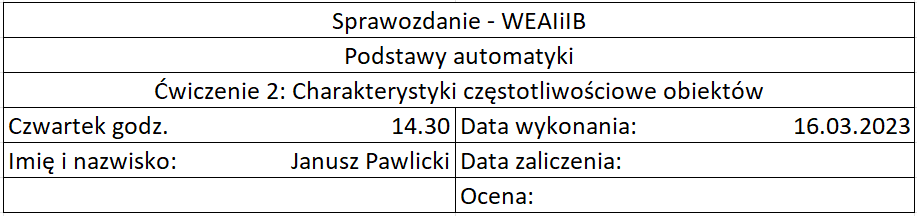

## 1. Wstęp

Celem ćwiczenia jest zapoznanie się z charakterystykami częstotliwościowymi podstawowych obiektów dynamicznych. Podczas ćwiczenia należy zbadać charakterystyki częstotliwościowe tych samych obiektów, które były badane podczas poprzedniego ćwiczenia.

Rys. 1 Wymuszenie sinusoidalne postaci *A* sin(wt) na obiekt (charakterystyka częstotliwościowa)

 Badane będą następujące dwa podstawowe typy charakterystyk częstotliwościowych:

- **Charakterystyka częstotliwościowa amplitudowo - fazowa. **Jest ona wykreślana na płaszczyźnie zespolonej i jest ona miejscem geometrycznym końca wektora, którego współrzędnymi są: Re( G(jω)) oraz Im ( G(jω)) przy zmianie pulsacji ω w zakresie od zera do nieskończoności, gdzie G(jω) jest transmitancją widmową obiektu.

- **Charakterystyka częstotliwościowa logarytmiczna modułu i fazy.** Są to wykresy modułu i fazy transmitancji widmowej G(jω) w funkcji pulsacji ω , przy czym zmienna niezależna ω jest podana w skali logarytmicznej (tj. w równych odstępach np. 0.1 1 10 ... ). Moduł transmitancji jest podawany w decybelach [dB], czyli jest on równy 20 log( | G(jω)| ), faza jest podawana w stopniach.

## 2 Przebieg laboratorium

### 2.1 Inercyjny I rzędu

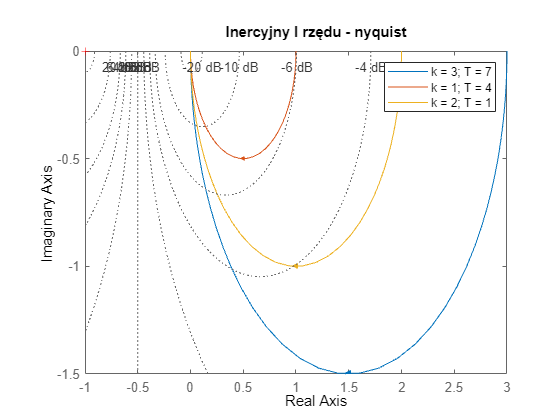

k = 3;
T = 7;
k1 = 1;
T1 = 4;
k2 = 2;
T2 = 1;


licz = [0, k];
mian = [T, 1];
licz1 = [0, k1];
mian1 = [T1, 1];
licz2 = [0, k2];
mian2 = [T2, 1];


G = tf(licz, mian);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G, plotoptions);
hold on
nyquist(licz1, mian1);
nyquist(licz2, mian2);
title('Inercyjny I rzędu - nyquist')
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
hold off;

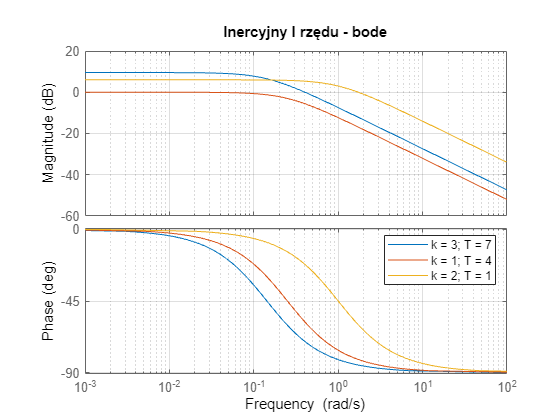


bode(licz, mian);
hold on;
bode(licz1, mian1);
bode(licz2, mian2);
title('Inercyjny I rzędu - bode')
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
hold off;

### 2.2 Inercyjny II rzędu

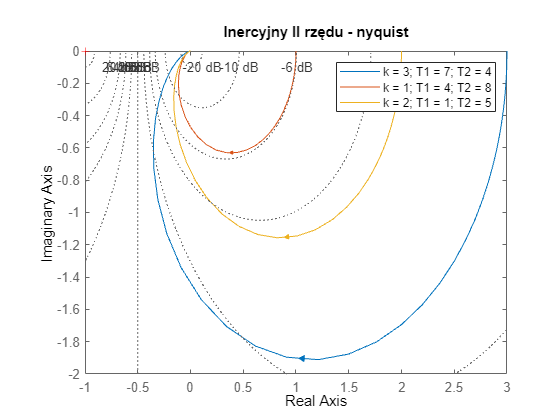

clear
k = 3;
T1 = 7;
T2 = 4;


k1 = 1;
T11 = 4;
T21 = 8;

k2 = 2;
T111 = 1;
T211 = 5;

licz = [0, 0, k];
mian = [T1 * T2, T1 + T2, 1];
licz1 = [0, 0, k1];
mian1 = [T11 * T21, T11 + T21, 1];
licz2 = [0, 0, k2];
mian2 = [T111 * T211, T111 + T211, 1];

G = tf(licz, mian);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G, plotoptions);
hold on
nyquist(licz1, mian1);
nyquist(licz2, mian2);
title('Inercyjny II rzędu - nyquist')
legend('k = 3; T1 = 7; T2 = 4', 'k = 1; T1 = 4; T2 = 8', 'k = 2; T1 = 1; T2 = 5')
grid on;
hold off;

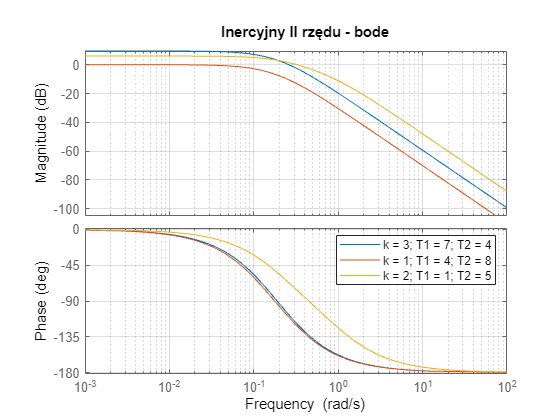


bode(licz, mian);
hold on;
bode(licz1, mian1);
bode(licz2, mian2);
title('Inercyjny II rzędu - bode')
legend('k = 3; T1 = 7; T2 = 4', 'k = 1; T1 = 4; T2 = 8', 'k = 2; T1 = 1; T2 = 5')
grid on;
hold off;

### 2.3 Inercyjny II rzędu (inna postać)

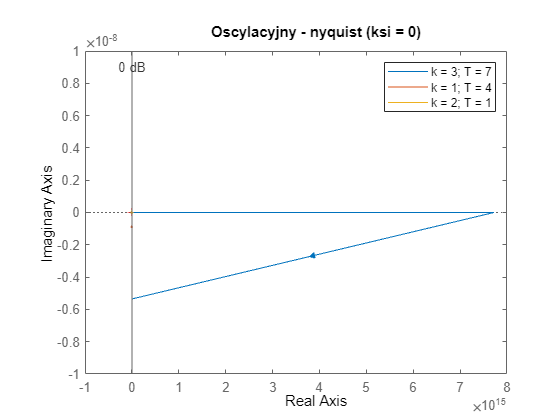

clear

k = 3;
T = 7;
k1 = 1;
T1 = 4;
k2 = 2;
T2 = 1;
ksi0 = 0;
ksi1 = 0.7;
ksi2 = 1;
ksi3 = 1.3;


%Układ oscylacyjny nietłumiony

licz = [0, 0, k];
mian = [T^2 ,2*ksi0*T ,1];
licz1 = [0, 0, k1];
mian1 = [T1^2 ,2*ksi0*T1 ,1];
licz2 = [0, 0, k2];
mian2 = [T2^2 ,2*ksi0*T2 ,1];

G = tf(licz, mian);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G, plotoptions);
hold on
nyquist(licz1, mian1);
nyquist(licz2, mian2);
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
title('Oscylacyjny - nyquist (ksi = 0)')
hold off

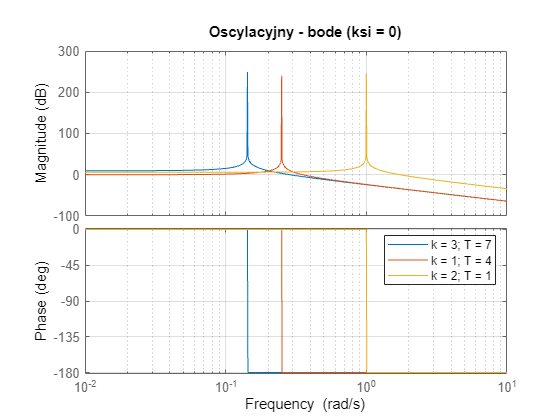


bode(licz, mian)
hold on
bode(licz1, mian1)
bode(licz2, mian2)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
title('Oscylacyjny - bode (ksi = 0)')
hold off

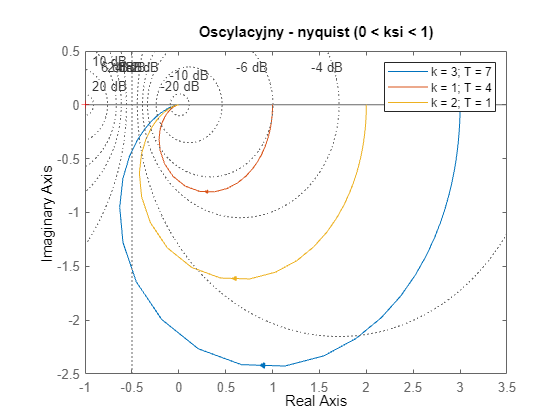


% Układ oscylacyjny tłumiony

licz3 = [0, 0, k];
mian3 = [T^2 ,2*ksi1*T ,1];
licz4 = [0, 0, k1];
mian4 = [T1^2 ,2*ksi1*T1 ,1];
licz5 = [0, 0, k2];
mian5 = [T2^2 ,2*ksi1*T2 ,1];


G = tf(licz3, mian3);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G, plotoptions);
hold on 
nyquist(licz4, mian4) 
nyquist(licz5, mian5)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
title('Oscylacyjny - nyquist (0 < ksi < 1)')
hold off

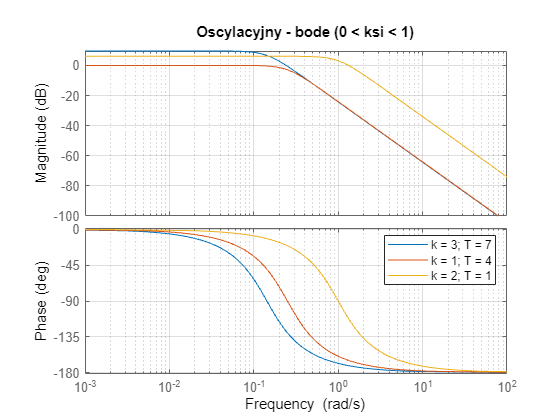


bode(licz3, mian3)
hold on
bode(licz4, mian4)
bode(licz5, mian5)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
title('Oscylacyjny - bode (0 < ksi < 1)')
hold off

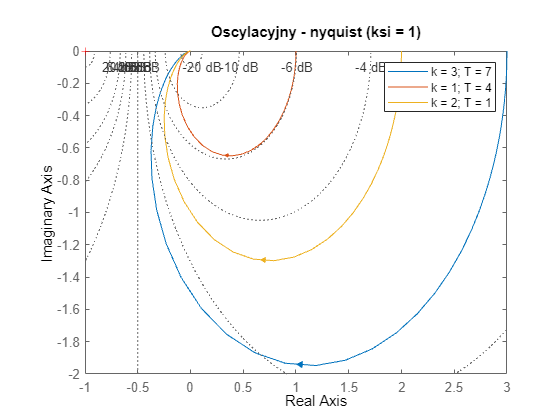


 % Układ aperiodyczny krytyczny 

licz6 = [0, 0, k];
mian6 = [T^2 ,2*ksi2*T ,1];
licz7 = [0, 0, k1];
mian7 = [T1^2 ,2*ksi2*T1 ,1];
licz8 = [0, 0, k2];
mian8 = [T2^2 ,2*ksi2*T2 ,1];

G = tf(licz6, mian6);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G, plotoptions);
hold on 
nyquist(licz7, mian7) 
nyquist(licz8, mian8)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
title('Oscylacyjny - nyquist (ksi = 1)')
hold off

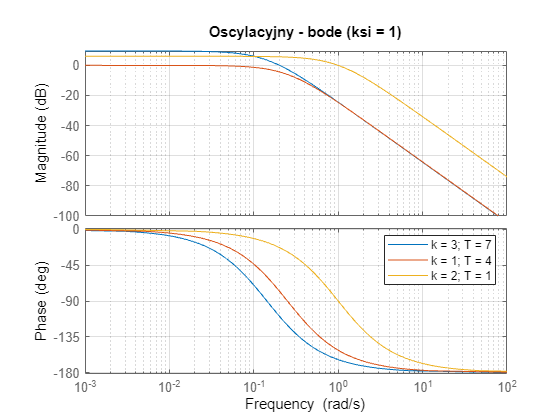


bode(licz6, mian6)
hold on
bode(licz7, mian7)
bode(licz8, mian8)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
title('Oscylacyjny - bode (ksi = 1)')
hold off

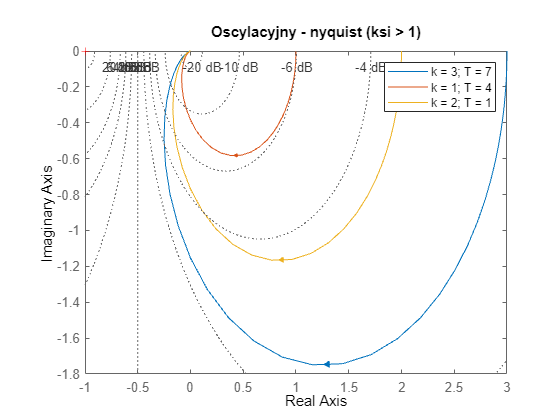


% Układ aperiodyczny

licz9 = [0, 0, k];
mian9 = [T^2 ,2*ksi3*T ,1];
licz10 = [0, 0, k1];
mian10= [T1^2 ,2*ksi3*T1 ,1];
licz11 = [0, 0, k2];
mian11= [T2^2 ,2*ksi3*T2 ,1];

G = tf(licz9, mian9);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G, plotoptions);
hold on 
nyquist(licz10, mian10)
nyquist(licz11, mian11)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
title('Oscylacyjny - nyquist (ksi > 1)')
hold off

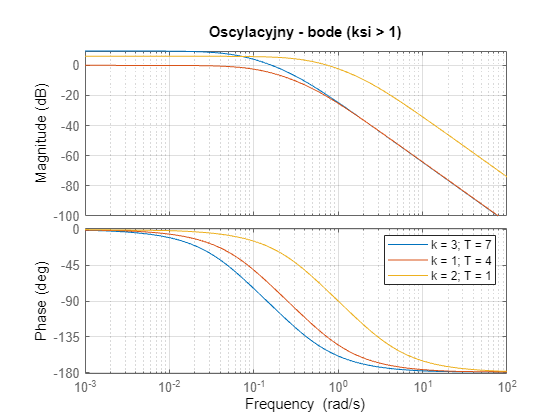


bode(licz9, mian9)
hold on
bode(licz10, mian10)
bode(licz11, mian11)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
title('Oscylacyjny - bode (ksi > 1)')
hold off

### 2.4 Całkujący rzeczywisty 

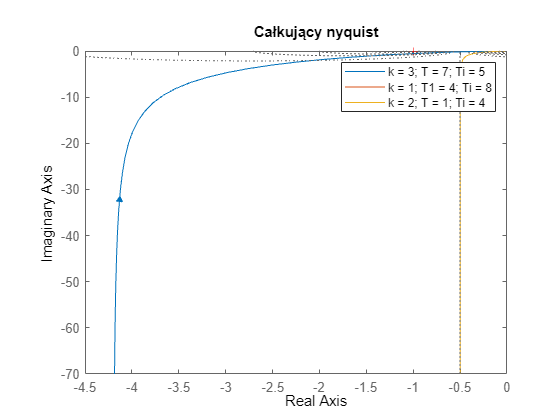

k = 3;
T = 7;
Ti = 5;
k1 = 1;
T1 = 4;
Ti1 = 8;
k2 = 2;
T2 = 1;
Ti2 = 4;

licz = [0, 0, k];
mian = [T * Ti, Ti, 0];
licz1 = [0, 0, k1];
mian1 = [T1 * Ti1, Ti1, 0];
licz2 = [0, 0, k2];
mian2 = [T2 * Ti2, Ti2, 0];

G = tf(licz, mian);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G, plotoptions);
hold on
nyquist(licz1, mian1);
nyquist(licz2, mian2);
title('Całkujący nyquist')
legend('k = 3; T = 7; Ti = 5', 'k = 1; T1 = 4; Ti = 8', 'k = 2; T = 1; Ti = 4')
grid on;
hold off

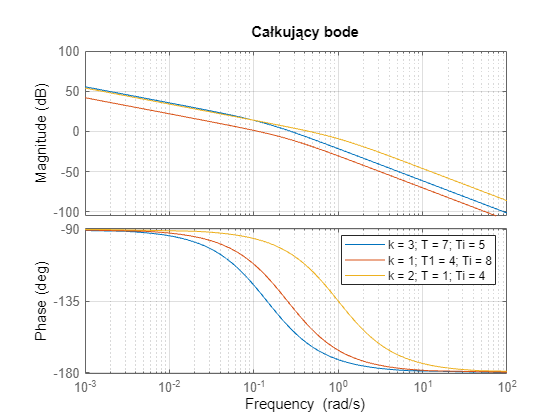


bode(licz, mian)
hold on
bode(licz1, mian1)
bode(licz2, mian2)
title('Całkujący bode')
legend('k = 3; T = 7; Ti = 5', 'k = 1; T1 = 4; Ti = 8', 'k = 2; T = 1; Ti = 4')
grid on;
hold off

### 2.5 Różniczkujący rzeczywisty

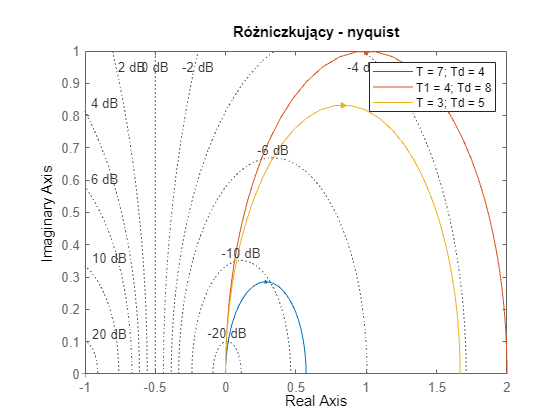

T = 7;
Td = 4;
T1 = 4;
Td1 = 8;
T2 = 3;
Td2 = 5;

licz = [Td, 0];
mian = [T, 1];
licz1 = [Td1, 0];
mian1 = [T1, 1];
licz2 = [Td2, 0];
mian2 = [T2, 1];

G = tf(licz, mian);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G, plotoptions);
hold on
nyquist(licz1, mian1);
nyquist(licz2, mian2);
legend('T = 7; Td = 4', 'T1 = 4; Td = 8', 'T = 3; Td = 5')
title('Różniczkujący - nyquist')
grid on;
hold off

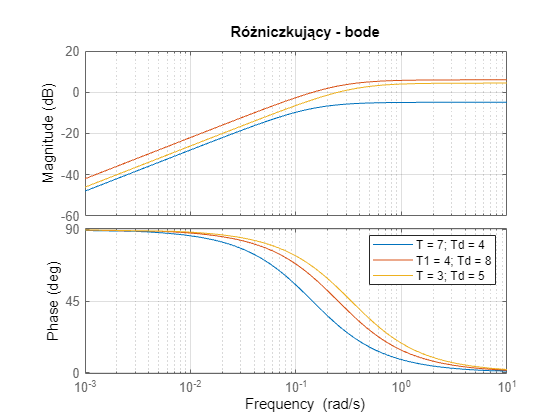


bode(licz, mian)
hold on
bode(licz1, mian1)
bode(licz2, mian2)
legend('T = 7; Td = 4', 'T1 = 4; Td = 8', 'T = 3; Td = 5')
title('Różniczkujący - bode')
grid on;
hold off

### 2.6 Inercyjny I rzędu z opóźnieniem

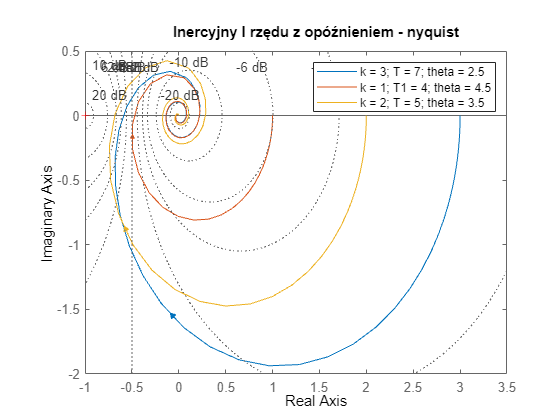

n = 5;

k = 3;
T = 7;
theta = 2.5;
k1 = 1;
T1 = 4;
theta1 = 4.5;
k2 = 2;
T2 = 5;
theta2 = 3.5;

[licz_op, mian_op] = pade(theta, n);
[licz_op1, mian_op1] = pade(theta1, n);
[licz_op2, mian_op2] = pade(theta2, n);

licz_iner = [0,k];
mian_iner = [T,1];
licz_iner1 = [0,k1];
mian_iner1 = [T1,1];
licz_iner2 = [0,k2];
mian_iner2 = [T2,1];

[licz, mian] = series(licz_op, mian_op, licz_iner, mian_iner);
[licz1, mian1] = series(licz_op1, mian_op1, licz_iner1, mian_iner1);
[licz2, mian2] = series(licz_op2, mian_op2, licz_iner2, mian_iner2);

G = tf(licz, mian);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G, plotoptions);
hold on
nyquist(licz1, mian1);
nyquist(licz2, mian2);
legend('k = 3; T = 7; theta = 2.5', 'k = 1; T1 = 4; theta = 4.5','k = 2; T = 5; theta = 3.5')
title('Inercyjny I rzędu z opóźnieniem - nyquist')
grid on;
hold off

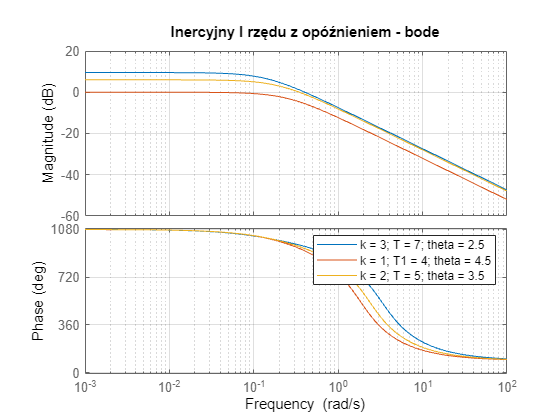


bode(licz, mian)
hold on
bode(licz1, mian1)
bode(licz2, mian2)
legend('k = 3; T = 7; theta = 2.5', 'k = 1; T1 = 4; theta = 4.5','k = 2; T = 5; theta = 3.5')
title('Inercyjny I rzędu z opóźnieniem - bode')
grid on;
hold off

## 3. Wnioski

Ćwiczenie nie sprawiło mi trudności. Było przyjemnym przypomnieniem wiadomości z poprzedniego smestru. Męczącą częścią ćwiczenia było przypisywanie zmiennych i ciągłe pisanie zmiennych licz i mian potrzebnych do stworzenia wykresów. Najdłużej zajęła mi część z układem inercyjnym II rzędu z opóźnieniem, ponieważ było w nim najwięcej przypadków. Wynikało to z rodzaji układu w zależności od ksi: (ksi = 0 - układ nietłumiony, 0 < ksi < 1 - układ tłumiony, ksi = 1 - układ aperiodyczny krytyczny, ksi > 1 - układ aperiodyczny).